7.14 （性能）实时脚本

由张志涌编写、修改于 2023.1。

性能计算

y0=[1,0];
K=13;
Tol=10.^(-K:1:-1)';
F={@ode23,@ode45,@ode113};
TSE=zeros(K,3,3);
for k = 1:K
    tol = Tol(k);
    opts = odeset('reltol',tol,'abstol',tol,'refine',1);
    for jj=1:3
        tic
        [t,y] = feval(F{jj},@harmonic,[0,10*pi],y0',opts);
        TSE(k,3,jj) = toc;                      %Time
        TSE(k,2,jj) = length(t)-1;              %Steps
        TSE(k,1,jj) = max(abs(y(end,:)-y0));    %Error
    end
end

绘图

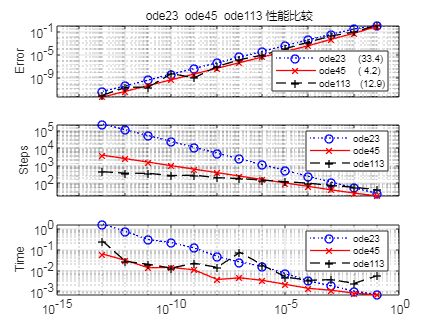

clf
set(gcf,'Color','w')
B=squeeze(TSE(:,1,:)./Tol);
bm=num2str(mean(B)','%2.1f');
ytk={10.^[-9,-5,-1],10.^(1:5),10.^(-4:0)};
yLb={'Error','Steps','Time'};
L23={'ode23  ','ode45  ','ode113 '};
L1={['ode23 　(',bm(1,:),')'];['ode45 　(',bm(2,:),')'];['ode113　(',bm(3,:),')']};
for jj=1:3
    subplot(3,1,jj)
    loglog(Tol,TSE(:,jj,1),'ob:',Tol,TSE(:,jj,2),'xr-',Tol,TSE(:,jj,3),'+k--','LineWidth',1)
    grid on,grid minor
    if jj==1
        legend(L1,'Location','SouthEast')
    else
        legend(L23,'Location','NorthEast')
    end
    if jj~=3,xticklabels(''),end
    yticks(ytk{jj})
    ylabel(yLb{jj})
end
subplot(3,1,1)
title([[L23{:}],'性能比较'])

function ydot = harmonic(t,y)
ydot = [y(2); -y(1)];
end
